# Difference methods for solving boundary value problems for ODE

## Taks 1

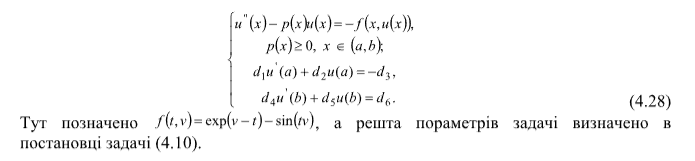

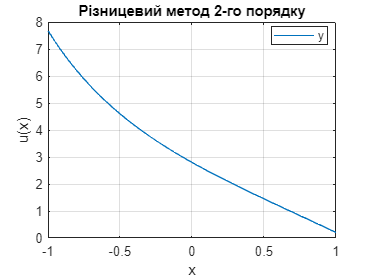

a = -1; b = 1;
p = @(x)(acos(x));
f = @(t, v)(exp(1 - t) - sin(t));

D = [1, 1, 1, 1, 17, 1];
n = 51;

[X, Y] = m_grid2(p, f, a, b, D, n, h);

plot(X, Y)
title('Різницевий метод 2-го порядку'), xlabel('x'), ylabel('u(x)');
legend('y','u(x)','Location','Best'), grid on;

function [X, Y] = m_grid2(pfun, ffun, a, b, D, n, h)
    X = linspace(a, b, n);
    
    n1 = n - 1; hh = h .* h; h2 = 2 .* h;
    maxIter = 100; % максимальна кількість ітерацій
    tol = 1e-6; % критерій зупинки
    Y_prev = ones(n, 1);
    for iter = 1:maxIter
        % обчислення коефіцієнтів з урахуванням лінеаризації
        A = ones(n, 1); B = A; C = A; F = A;
        A(1) = 0; C(1) = D(1) .* (2 + hh .* pfun(a)) - D(2) .* h2;
        B(1) = 2 .* D(1); F(1) = D(3) .* h2 + D(1) .* hh .* ffun(a);
        for k = 2: n1
            x = X(k);
            % застосування лінеаризації до ffun
            ffun_lin = linearize(ffun, x);
            C(k) = 2 + hh .* pfun(x); F(k) = hh .* ffun_lin;
        end
        A(n) = 2 .* D(4); C(n) = D(4) .* (2 + hh .* pfun(b)) + D(5) .* h2;
        B(n) = 0; F(n) = D(4) .* hh .* ffun(b) + D(6) .* h2;
        % розв'язання СЛАР
        [Y, AL, er] = m_progm(A, C, B, F);
        if er
            [Y, AL] = m_progn(A, C, B, F);
        end
        % перевірка критерію зупинки
        if max(abs(Y - Y_prev)) < tol
            break;
        end
        Y_prev = Y;
    end
    
    [Y, AL, er] = m_progm(A, C, B, F);
    if er
        [Y, AL] = m_progn(A, C, B, F);
    end
end 

function ffun_lin = linearize(ffun, x)
    h = 1e-6; % малий крок для обчислення похідної

    % обчислення похідної за допомогою центральної різницевої формули
    df_dx = (ffun(x + h) - ffun(x - h)) / (2 * h);

    ffun_lin = ffun(x) + df_dx * (x - x); % перший член ряду Тейлора
end



function [y, alfa, err]  =  m_progm(a, c, b, f) 
    n = length(c); err = 0; k = 0;
    while k < n && ~err
        k = k + 1;
        err = err | abs(c(k))< abs(a(k)) + abs(b(k));
    end
    alfa = zeros(1, n); y = alfa;
    if err
        return
    end
    n1 = n - 1;
    % пряма прогонка:
    beta = alfa;
    for k = 1 : n1
        j = k + 1; z = c(k) - a(k) .* alfa(k);
        alfa(j) = b(k) ./ z; beta(j) = (f(k) + a(k) .* beta(k)) ./ z;
    end
    % зворотна прогонка:
    y(n) = (f(n) + a(n) .* beta(n)) ./ (c(n) - a(n) .* alfa(n));
    for k = n1 : -1 : 1
        j = k+1; y(k) = alfa(j) .* y(j) + beta(j);
    end
end







function [y, alfa]  =  m_progn(a, c, b, f) 
    n = length(c); n1 = n - 1;
    alfa = zeros(1, n); y = alfa;
    beta = alfa; ka = ones(1, n); te = alfa;
    C = c(1); A = a(2); F = f(1); Q = f(2);
    for k = 1 : n1
        j = k + 1;
        if abs(C)<= abs(b(k))
            alfa(j) = b(k) ./ C; beta(j) = F ./ C;
            C = c(j) - A .* alfa(j); F = Q + A .* beta(j);
            te(j) = ka(k); ka(j) = j;
            if k ~= n1
                j = j + 1; A = a(j); Q = f(j);
            end
        else
            alfa(j) = C ./ b(k); beta(j) = -F ./ b(k);
            C = c(j) .* alfa(j) - A; F = Q - c(j) .* beta(j);
            te(j) = j; ka(j) = ka(k);
            if k ~= n1
                j1 = j; j = j + 1;
                A = a(j) .* alfa(j1); Q = f(j) + a(j) .* beta(j1);
            end
        end
    end
    % зворотня прогонка:
    y(ka(n)) =F ./ C;
    for k=n1 : -1 : 1
        j = k + 1; y(te(j)) = alfa(j) .* y(ka(j)) + beta(j);
    end
end